# Live Report Information During Network Training

This example shows how to live report custom information during network training.

Load sample data.$\mathrm{asdasdasdads}$

[XTrain,YTrain] = digitTrain4DArrayData;
numClasses = numel(categories(YTrain));

Contruct network architecture.

layers = [...
    imageInputLayer([28 28 1],'Normalization','none')
    convolution2dLayer(6,20)
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

Specify the training options. Set `'OutputFcn'` to be the `updatePlot` function. For quick training, set `'MaxEpochs'` to 5 and `'InitialLearnRate'` to 0.1. 

Training on single GPU.
|=========================================================================================|
|     Epoch    |   Iteration  | Time Elapsed |  Mini-batch  |  Mini-batch  | Base Learning|
|              |              |  (seconds)   |     Loss     |   Accuracy   |     Rate     |
|=========================================================================================|


|            1 |            1 |         0.10 |       2.3022 |       12.50% |       0.1000 |


|            2 |           50 |         1.95 |       0.8718 |       71.09% |       0.1000 |


|            3 |          100 |         3.88 |       0.1573 |       96.88% |       0.1000 |


|            4 |          150 |         5.77 |       0.0697 |       98.44% |       0.1000 |


|            5 |          195 |         7.52 |       0.0459 |       99.22% |       0.1000 |
|=========================================================================================|


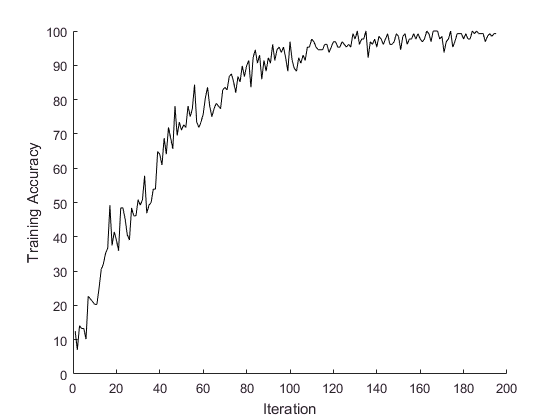

options = trainingOptions('sgdm',...
    'MaxEpochs',5,...
    'InitialLearnRate',0.1,...
    'OutputFcn',@updatePlot);

net = trainNetwork(XTrain,YTrain,layers,options);

function updatePlot(info)
%% updatePlot    Update plot with training information
%    updatePlot(info) plots info.TrainingAccuracy against info.Iteration.
%    The function updates the plot with each function call. 

persistent plotObj
 
switch info.State
    case "start"
        figure
        plotObj = animatedline;
        xlabel("Iteration")
        ylabel("Training Accuracy")
    case "iteration"
        addpoints(plotObj,info.Iteration,info.TrainingAccuracy);
        drawnow limitrate nocallbacks
    otherwise
end
 
end